**Modeling Battery Charging Profile**

Using  MATLAB Curve Fitting Toolbox, fit the equation$V\left(t\right)=V_{\max } \left(1-e^{-\frac{t}{\mathrm{RC}}} \right)$  and model the battery charging profile as a simple RC-circuit analog.

-  Simulating how different capacitance(C), resistances(R), and max voltages(Vmax) change the Voltage vs. Time charging graph.

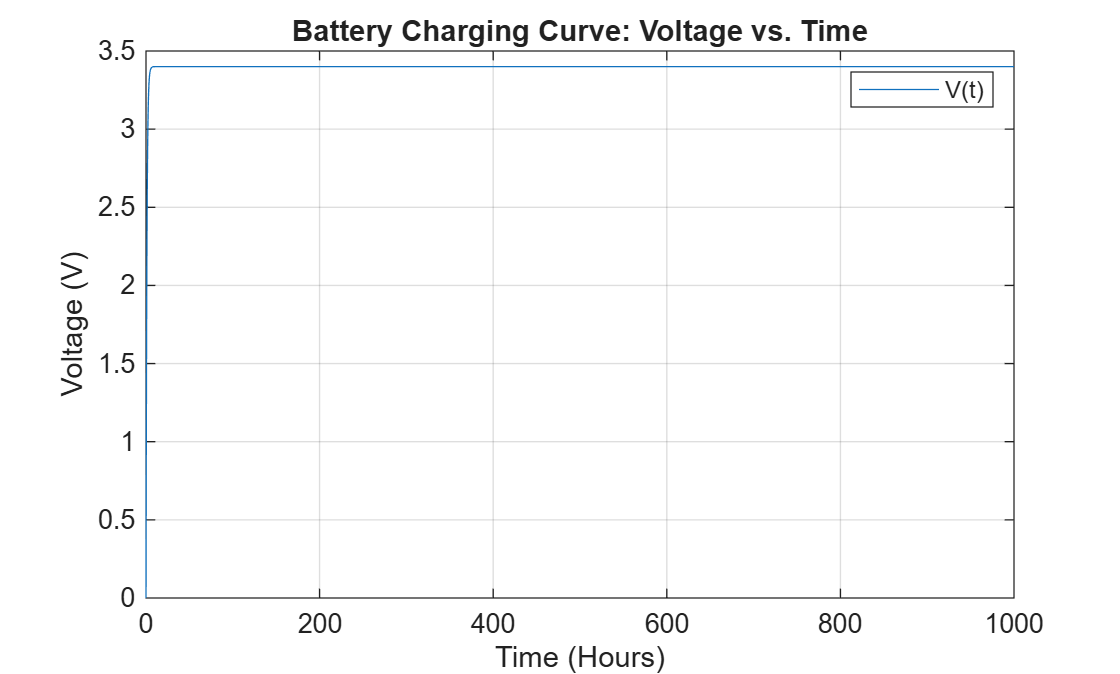

Vmax = 3.4;    %[Volt]
R = 1;        %[Ohm]
C = 1;        %[farad]
t = linspace(0,1000, 10000);            %[Second]

V_t = Vmax * (1 - exp(-t / (R * C)));

figure;
simple_charge_graph = plot(t,V_t,"DisplayName","V(t)");
legend
grid on
xlabel("Time (Hours)")
ylabel("Voltage (V)")
title("Battery Charging Curve: Voltage vs. Time")

        2. Loading the battery dataset

- **Battery Cell Data**

The measurements from LIBs are collected during cycling tests under fast-charging conditions, using a 48-channel Arbin LBT potentiostat within a temperature-controlled chamber set at 30°C. This example focuses a single cell that is cycled to failure (80% state of health) in order to provide a comprehensive view of its performance over time. The cycling sequence exercises the battery cell with dynamic fast charging and constant 4C discharging. The cell data includes essential measurements and per-cycle summaries:

- Date Time: Recorded in date-time format, which may be reset during a cycle due to data collection errors.

- Cycle Index: An integer identifying the cycle number.

- Step Index: An integer identifying the steps within the fast-charging policy.

- Current: Measured in amperes (A).

- Voltage: Measured in volts (V).

- Temperature: Measured in degrees Celsius (°C).

dataFile = matlab.internal.examples.downloadSupportFile("predmaint","batteryagingdata/singlecell/v1/singleCellLifeTimeData.zip");
unzip(dataFile)
load("singleCellLifeTimeData.mat")

=== Single Cell Battery Life Time Dataset (First 5 Rows) ===

head(data,5)

    Data_Point    Test_Time          DateTime          Step_Time    Step_Index    Cycle_Index    Current    Voltage    Charge_Capacity    Discharge_Capacity    Charge_Energy    Discharge_Energy       dV/dt       Internal_Resistance    Temperature
    __________    _________    ____________________    _________    __________    ___________    _______    _______    _______________    __________________    _____________    ________________    ___________    ___________________    ___________

-  **Parsing and Segment data**

To identify the cycling phases and modes and based on the measurements, use `batteryTestDataParser`. This function enables raw data visualization, aids in identifying anomalies, and prepare high-quality data.

bParser = batteryTestDataParser(data);
bParser.CurrentVariable = 'Current';
bParser.VoltageVariable= "Voltage";
bParser.TimeVariable = "DateTime";
bParser.CycleIndexVariable = 'Cycle_Index';
bParser.StepIndexVariable = 'Step_Index';  

=== Single Cell Battery Life Time Dataset (First 5 Rows) - Updated ===

segmentedRawDataTable = segmentData(bParser);
head(segmentedRawDataTable,5)

    Data_Point    Test_Time          DateTime          Step_Time    Step_Index    Cycle_Index    Current    Voltage    Charge_Capacity    Discharge_Capacity    Charge_Energy    Discharge_Energy       dV/dt       Internal_Resistance    Temperature    CyclingModes    CyclingPhases    IsValid
    __________    _________    ____________________    _________    __________    ___________    _______    _______    _______________    __________________    _____________    ________________    <s

- **Extract only the valid "Charge" phase data for Cycle 1**

chargingData = segmentedRawDataTable(segmentedRawDataTable.Cycle_Index == 1 & ...
                                     segmentedRawDataTable.CyclingPhases == "Charge", :);
chargingData.TimeInSeconds = seconds(chargingData.DateTime - chargingData.DateTime(1));

- **Create the Plot**

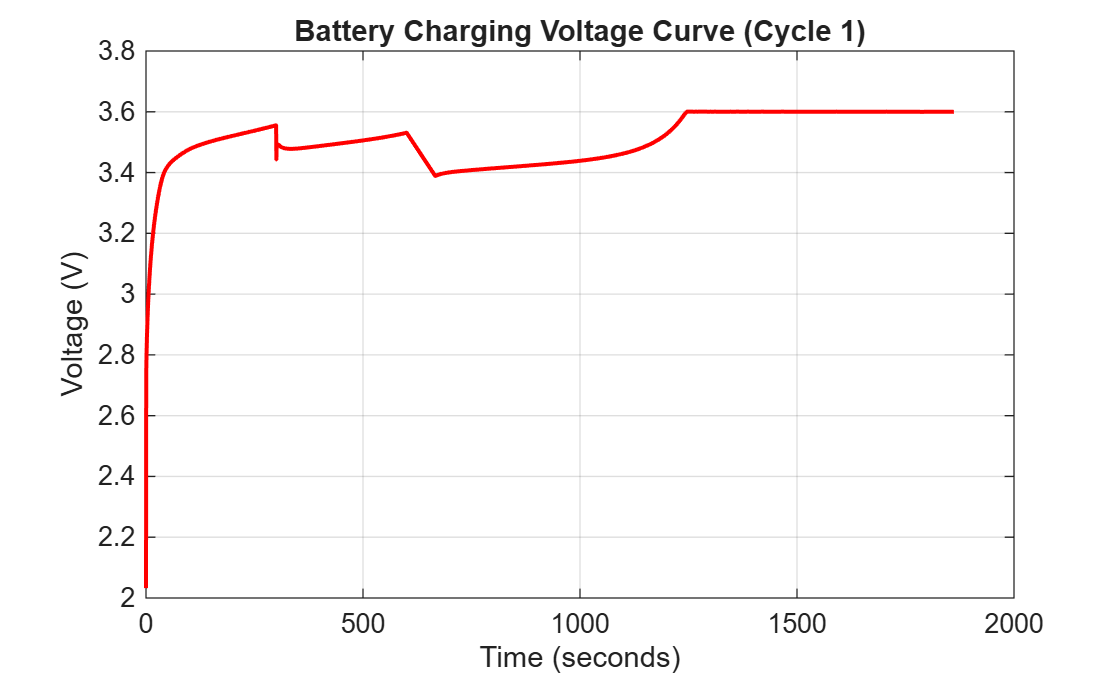

figure;
plot(chargingData.TimeInSeconds, chargingData.Voltage, '-r', 'LineWidth', 1.5);

xlabel('Time (seconds)');
ylabel('Voltage (V)');
title('Battery Charging Voltage Curve (Cycle 1)');
grid on;

totalPoints = height(chargingData);
evenIndices = round(linspace(1, totalPoints, 20));

% 4. Extract those 20 specific points
evenTime = chargingData.TimeInSeconds(evenIndices);
evenVoltage = chargingData.Voltage(evenIndices);

% 5. Create the plot
figure;
% Plot a faint line in the background so you can see the trend, 
% then overlay the 20 distinct points as red circles
plot(chargingData.TimeInSeconds, chargingData.Voltage, ':k', 'LineWidth', 1); % Dotted background line
hold on;
plot(evenTime, evenVoltage, 'or', 'MarkerSize', 5, 'MarkerFaceColor', 'r'); % 20 Evenly-spaced points
hold off;

xlabel('Time (seconds)');
ylabel('Voltage (V)');
title('20 Battery Charging Voltage Points');
grid on;

- **Plot the data and the fitted curve**

% 1. Define custom model with Vmax and tau as coefficients
ft = fittype('Vmax * (1 - exp(-t / tau))', ...
    'independent', 't', ...
    'coefficients', {'Vmax', 'tau'});

% 2. Set options with safety bounds and starting guesses
opts = fitoptions('Method', 'NonlinearLeastSquares');
opts.StartPoint = [3.6, 100];   % Start Vmax at 3.6, tau at 100
opts.Lower = [0, 0.001];        % Vmax > 0, tau > 0 (prevents Inf errors)
opts.Upper = [Inf, Inf];

% 3. Fit the model to your data points
[fitResult, gof] = fit(evenTime, evenVoltage, ft, opts);

% 4. Display results
disp(fitResult);

     General model:
     fitResult(t) = Vmax * (1 - exp(-t / tau))
     Coefficients (with 95% confidence bounds):
       Vmax =       3.478  (3.23, 3.725)
       tau =      0.3244  (0.0316, 0.6172)


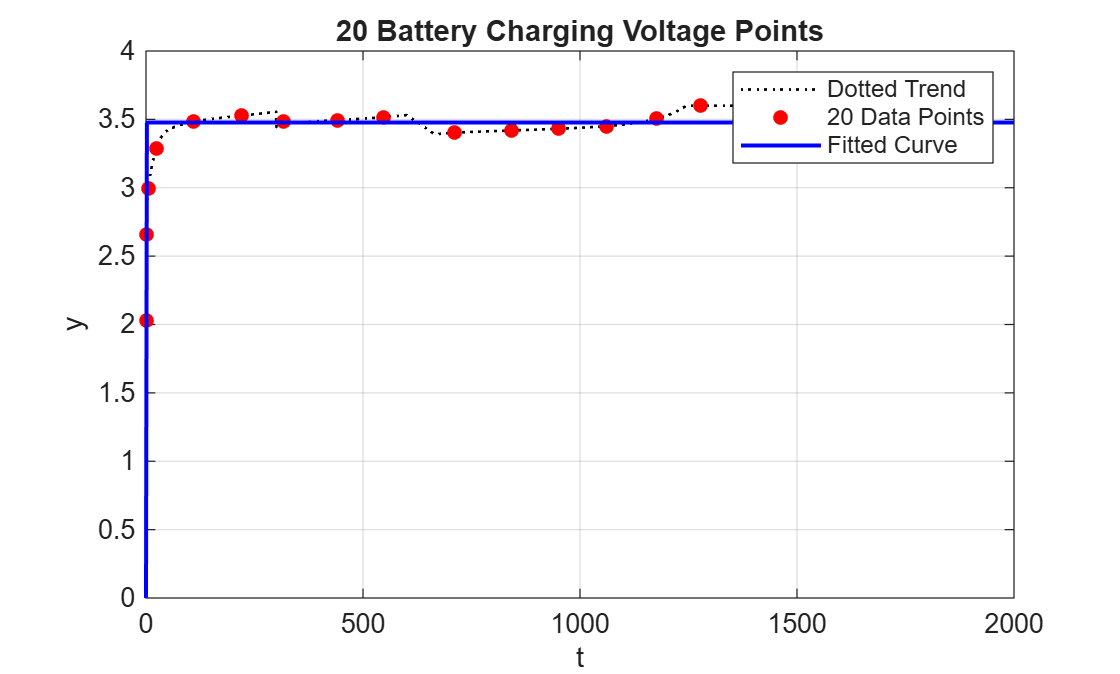


% 5. Plot the fitted curve over your points
hold on;
plot(fitResult, 'b-');
legend('Dotted Trend', '20 Data Points', 'Fitted Curve');
hold off;